# 例1.5（圧縮処理）

村松正吾　「多次元信号・画像処理の基礎と展開」

動作確認： MATLAB R2017a

## 画像データのダウンロード

% utilities.download_img

## 画像データの読込

V = imread('./data/barbara.png');

## 圧縮前のデータ量

dataInfo = whos('V');
fprintf('圧縮前のバイト数： %d [Bytes]\n',dataInfo.bytes)

圧縮前のバイト数： 1048576 [Bytes]


fprintf('圧縮前のビット数： %6.2f [bpp]\n',8*dataInfo.bytes/prod(dataInfo.size))

圧縮前のビット数：  32.00 [bpp]


## 圧縮前の画像表示

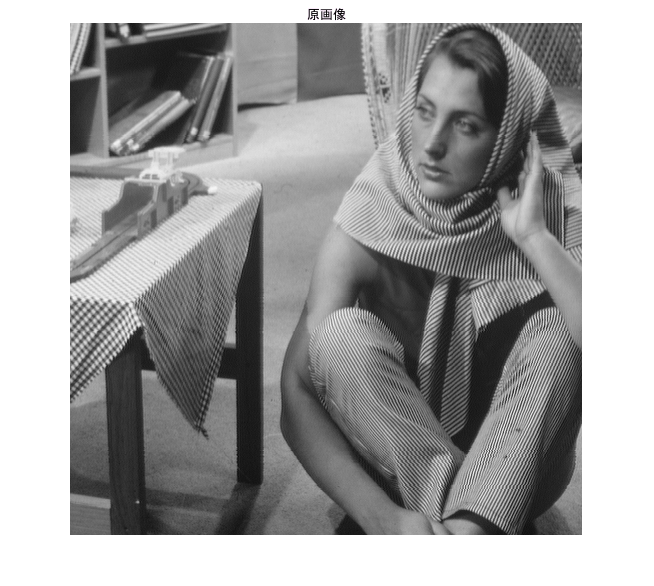

figure(1)
imshow(V)
title('原画像')

## JPEG圧縮

qFactor = 50; % 品質制御 [0,100]
imwrite(V,'./data/barbara.jpg','Quality',qFactor)

## 圧縮後のデータ量

fileInfo = dir('./data/barbara.jpg');
fprintf('圧縮後のバイト数： %d [Bytes]\n',fileInfo.bytes)

圧縮後のバイト数： 30728 [Bytes]


fprintf('圧縮後のビット数： %6.2f [bpp]\n',8*fileInfo.bytes/prod(dataInfo.size))

圧縮後のビット数：   0.94 [bpp]


## 圧縮後の画像表示

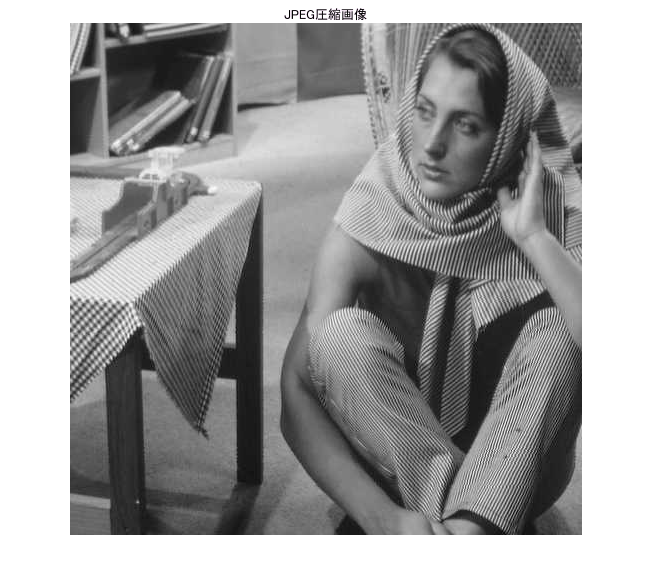

U = imread('./data/barbara.jpg');
figure(2)
imshow(U)
title('JPEG圧縮画像')

## 圧縮前後の差分画像表示

Y = imadjust(imabsdiff(U,V));

エラー: checkForSameSizeAndClass (line 8)
X と Y は同じクラスでなければなりません。
エラー: imabsdiff (line 42)
checkForSameSizeAndClass(X, Y, mfilename);

figure(3)
imshow(Y)
title('差分画像')

## ピーク信号対雑音比による誤差評価

fprintf('PSNR:  %6.2f [dB]\n',psnr(V,U))